## Execução com a ERMxSC02 (FSL@ANATEL/SC)

Conectado e respondendo à sua identificação:

disp('Propriedades:')

Propriedades:


callTCP = Analysers.Analyser.connTCP("10.48.10.241", 5025)

callTCP =   dictionary (string ⟼ string) with 6 entries:

    "Factory" ⟼ "Rohde_Schwarz"
    "model"   ⟼ "FSL_6"
    "serial"  ⟼ "100711/006"
    "version" ⟼ "2.30"
    "ip"      ⟼ "10.48.10.241"
    "port"    ⟼ "5025"


obj = Analysers.Analyser.instance(callTCP);

Analyer: Base de comando(Rohde_Schwarz), modelo (FSL_6).


obj.preAmp('On')

Analyer.sendCMD: Criando nova conexão TCP.


obj.setRes(10)
obj.setSpan(500)


% Portadora em 100.9 MHz
obj.setFreq(100900000)

% Obtém o traço
trace = obj.getTrace(1);
disp('Trace:')

Trace:


% Só as 5 primeiras linhas
disp(trace (1:5,:));

      freq        value 
    _________    _______

    1.009e+08    -75.759
    1.009e+08    -73.656
    1.009e+08     -72.68
    1.009e+08    -72.045
    1.009e+08     -71.61



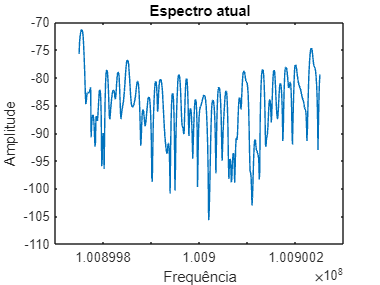


%% Plota o Trace
p = plot(trace.freq,trace.value,"DisplayName","value");

% Add xlabel, ylabel, title, and legend
xlabel("Frequência")
ylabel("Amplitude")
title("Espectro atual")

legend('off');

disp('Leitura do marcador:')

Leitura do marcador:


nivel = obj.getMarker(100900000, 1);
disp(nivel)

-86.1895904541




% Portadora em 101.7 MHz
obj.setFreq(101700000)

% Obtém o traço
trace = obj.getTrace(1);
disp('Trace:')

Trace:


% Só as 5 primeiras linhas
disp(trace (1:5,:));

      freq        value 
    _________    _______

    1.017e+08    -76.954
    1.017e+08    -80.135
    1.017e+08     -81.75
    1.017e+08    -83.292
    1.017e+08    -84.495



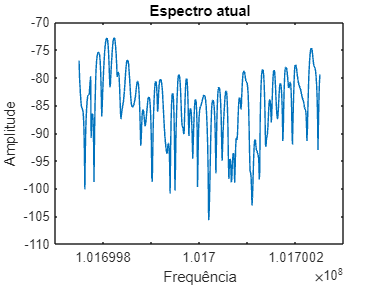


%% Plota o Trace
p = plot(trace.freq,trace.value,"DisplayName","value");

% Add xlabel, ylabel, title, and legend
xlabel("Frequência")
ylabel("Amplitude")
title("Espectro atual")

legend('off');

disp('Leitura do marcador:')

Leitura do marcador:


nivel = obj.getMarker(101700000, 1);
disp(nivel)

-86.1895904541



disp("As duas maiores emissoras da região estão com nível muito baixo.")

As duas maiores emissoras da região estão com nível muito baixo.



% Encerra ativamente a conexão
obj.disconnect()

disp("Pronto")

Pronto
